# Kelly Cosine Approximation

First, plot to compare between cosine and kelly cosine approximation

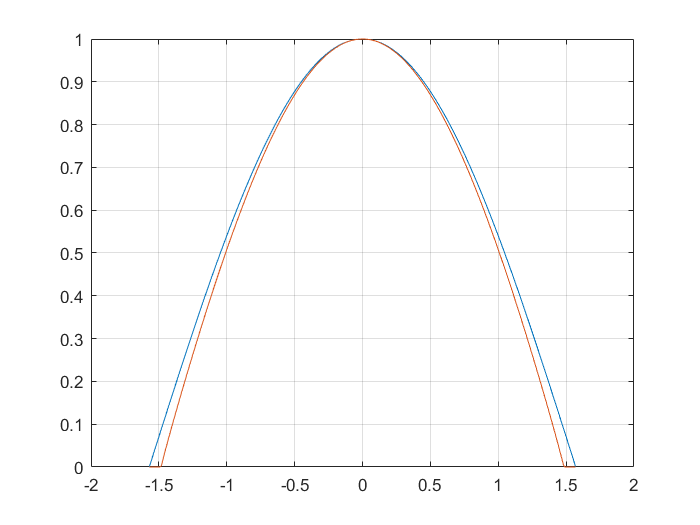

theta=-pi/2:0.01:pi/2;
y=cos(theta);

%Kelly cosine
kcos=zeros(1,length(theta));
for i=1:length(theta)
    th_s=abs(theta(i));
    if th_s<=pi/2
        kcos(i)=0;
    end
    if th_s<17*pi/36
        kcos(i)=(cos(1.059*th_s))^0.949;
    end

end

%plot
figure()
plot(theta,y)
hold on
plot(theta,kcos)
grid on

# Power generated

### 1. Calculation at multiple altitudes, case for sun-aero pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun-aero pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 2 in this section, because it corresponds to the sun-aero pointing mode.

% for i=1:length(angle)
%     kcos(1,i)=kcosine(angle(i));
% end
% 
% plot(angle, kcos)
% hold on
% plot(angle, cos(angle))

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

%eff_Psa=0.95;
%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=10;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 2;   %"sun-aero" pointing mode
orbit.a = (6371+300)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 2;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    orbit.O = 45;
        RAAN= orbit.O ;
        Power=sim('powerfrompropagator_kcos');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_saero(j,i)=mean(Pcollected);
        B_saero(j,i)=mean(beta);
    
    
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator_kcos');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_saero(j,i)=mean(Pcollected);
        B_saero(j,i)=mean(beta);
    end



for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator_kcos');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_saero(j,i)=mean(Pcollected);
        B_saero(j,i)=mean(beta);
    end
end